# Homework 2

## Task 1 

$(AB)^T = B^T A^T$, with $A$ being a $m \times n$ and $B$ being a $n \times p$ matrix. 

As$AB = \pmatrix{\sum\limits_{i=1}^n a_{1i} b_{i1} & \sum\limits_{i=1}^n a_{1i} b_{i2} & \ldots & \sum\limits_{i=1}^n a_{1i} b_{ip} \cr \sum\limits_{i=1}^n a_{2i} b_{i1} & \sum\limits_{i=1}^n a_{2i} b_{i2} & \ldots & \sum\limits_{i=1}^n a_{2i} b_{ip} \cr \vdots & \vdots & \ddots &\vdots \cr \sum\limits_{i=1}^n a_{mi} b_{i1} & \sum\limits_{i=1}^n a_{mi} b_{i2} & \cdots & \sum\limits_{i=1}^n a_{mi} b_{ip}},$ which is a $m\times p$ matrix, $(AB)^T = \pmatrix{\sum\limits_{i=1}^n a_{1i} b_{i1} & \sum\limits_{i=1}^n a_{2i} b_{i1} & \ldots & \sum\limits_{i=1}^n a_{mi} b_{i1} \cr \sum\limits_{i=1}^n a_{1i} b_{i2} & \sum\limits_{i=1}^n a_{2i} b_{i2} & \ldots & \sum\limits_{i=1}^n a_{mi} b_{i2} \cr \vdots & \vdots & \ddots &\vdots \cr \sum\limits_{i=1}^n a_{1i} b_{ip} & \sum\limits_{i=1}^n a_{2i} b_{ip} & \cdots & \sum\limits_{i=1}^n a_{mi} b_{ip}},$ which is a $p\times m$ matrix.

Also $B^TA^T = \pmatrix{{b_{11} & b_{12} & \cdots & b_{1n} \cr b_{21} & b_{22} & \cdots & b_{2n} \cr \vdots & \vdots & \ddots & \vdots \cr b_{p1} & b_{p2} & \cdots & b_{pn}}$ $\pmatrix{{a_{11} & a_{12} & \cdots & a_{1m} \cr a_{21} & a_{22} & \cdots & a_{2m} \cr \vdots & \vdots & \ddots & \vdots \cr a_{n1} & a_{n2} & \cdots & a_{nm}}$$=  \pmatrix{\sum\limits_{i=1}^n a_{1i} b_{i1} & \sum\limits_{i=1}^n a_{2i} b_{i1} & \ldots & \sum\limits_{i=1}^n a_{mi} b_{i1} \cr \sum\limits_{i=1}^n a_{1i} b_{i2} & \sum\limits_{i=1}^n a_{2i} b_{i2} & \ldots & \sum\limits_{i=1}^n a_{mi} b_{i2} \cr \vdots & \vdots & \ddots &\vdots \cr \sum\limits_{i=1}^n a_{1i} b_{ip} & \sum\limits_{i=1}^n a_{2i} b_{ip} & \cdots & \sum\limits_{i=1}^n a_{mi} b_{ip}},$ which is a $p \times m$ matrix 

and also eqal to $(AB)^T$. q.e.d

## Task 2

**objective: **minimize costs

**decision variables: **number of BusA for 800, number of BusB for 600, 

    coefficients: [800, 600] (minimize)

**constraints: **

9 drivers

10x BusA, 50 seats

8x BusB, 40 seats

total available busses: 9

total available seats: 820 ---> 400 Students, so 400 is the constraint

BusA = 10 busses and 50 seats

BusB = 8 busses and 40 seats

BusA +BusB <= 9

50*BusA + 40*BusB >= 400

BusA <= 10

BusB <= 8

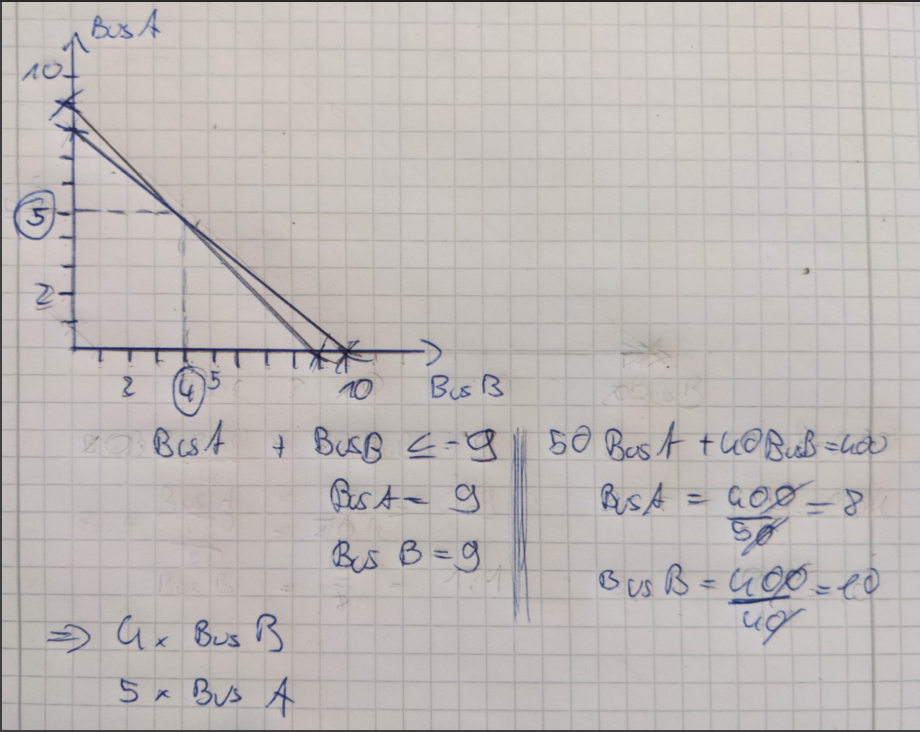

Graphical solution: 5x Bus A, 4x Bus B

% linprog solution

f = [800; 600] % costs to minimize
A = [1 1; -50 -40] % number of busses and number of seats
b = [9; -400] % number of busses and number of seats

lb = [0;0]
ub = [10;8] % number of busses is limited

res = linprog(f, A,b, [], [], lb, ub)

## Task 3

A = [3 1 1 2; 
     2 0 1 1; 
     3 3 0 3]
b = [4;
     3;
     1]

b is in subspace of A if b is a solution of linear combination of A

b is a solution if the rank of the argumented matrix equals the rank of the matrix

the rank can be derived from the number of non-zero rows of the reduced row-echolon form or by using the matlab function rank()

Ab = [3 1 1 2 4; 
     2 0 1 1 3; 
     3 3 0 3 1]

if rank(A) == rank(Ab)
   fprintf("solution found, b is in the subspace of V") 
else
   fprintf("no solution found, b is not in the subspace of V")
end


Result: b is not in the subspace of V

### Dimension Theorem 

% determine dimensions of null space and column space
dim_N_A = size(null(A), 2);

[A_rref, pivots_A] = rref(A);
dim_col_A = length(pivots_A);

%Dimension of column space of A plus the dimension of the null space of A
dim_sum = dim_N_A + dim_col_A;

rank_null = dim_sum == size(A, 2)


$\Rightarrow$Dimension-Theorem Holds

# Exercise 2

linprog arguments

f = (coeffs that make up the objective) --> [10,12] -->  [-10,-12] since the function minimizes by default, but we want to maximize

A = (total  inequality constrains) --> "each x requires y amounts" --> [3 3;2 4]

b = [120;150]

Aeq = []

beq = []

lb = [0;0]

ub = [100;100] (arbitrary large number which does not further constrain the solution

## Task 1

% create matrix
A = [1 2 3; 4 5 6; 7 8 9]

**put into reduced row echolon form** 

Requirements:  

1. the first non-zero entry of each row is 1

2. the first non-zero entry is to the right of the first non-zero entry in the previous row

3. rows made up entirely of zeros are at the bottom of the matrix

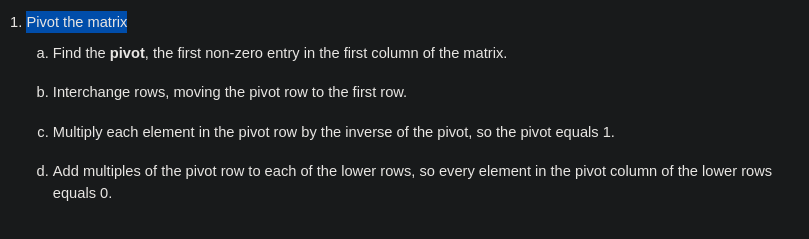

A = [1 2 3; 4 5 6; 7 8 9]

% round 1
pivot  = 1 

% first column -> all zero (but first) 
A(2,:) = A(2,:) + (A(1,:) * -4)
A(3,:) = A(3,:) + (A(1,:) * -7)


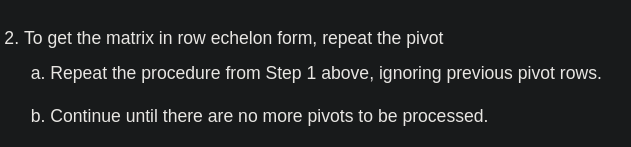


% round 2
pivot = -3

% make pivot 1
A(2,:) = A(2,:) * (-1/3) % inverse  of pivot
% make all below it 0
A(3,:) = A(3,:) + (A(2,:)*6)

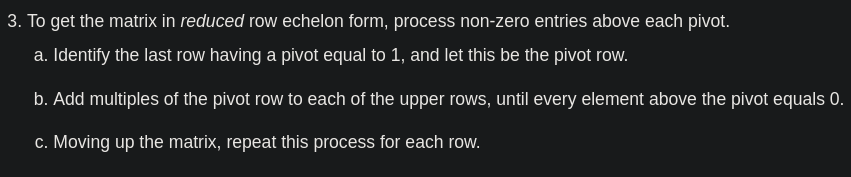

% make it reduced

pivot_row = 2

A(1,:) = A(1,:) + (A(pivot_row,:)*-2)

A_red_manually = A
A_red_manually


confirm results with `rref`

A = [1 2 3; 4 5 6; 7 8 9]
A_red = rref(A)
A_red

q.e.d

Bits and pieces you would need to make a function for it, but which are not relevant for this exercise yet.

% find pivot (1st non-zero, in 1st column)

k = 1
if A(k,1) > 0 || A(k,1) < 0 
    pivot_var = A(k,1)
    [pivot_row, pivot_col] = find(A == pivot_var)
else 
  while A(k,1) == 0 % iterate through 1st col
    k = k + 1
    if A(k,1) > 0 || A(k,1) < 0 % redundant check, but I leave it for now
        pivot_var = A(k,1)
        [pivot_row, pivot_col] = find(A == pivot_var)
    end
  end  
end


% interchange rows, moving the pivot row to the first row
[nrow_matrix,ncol_matrix] = size(A)
row_order = 1:nrow_matrix

if pivot_row ~= 1
   row_order_new = row_order
   row_order_new(row_order_new == pivot_row) = []
   row_order_new = [pivot_row, row_order_new] 
   pivot_row = 1
   A_rearranged = A(row_order_new,:)
else 
   A_rearranged = A 
end

% Multiply each element in the pivot row by the inverse of the pivot, so
% the pivot equals 1

A_rearranged(1,:) = A_rearranged(1,:) * 1/pivot_var % apply only on first row

% Add multiples of the pivot to each of the lower rows, so every element in
% the pivot column of the lower rows equals 0 


for i = 2:nrow_matrix
    if  A_rearranged(i,pivot_col) ~= 0 % check number in pivot column
        num_to_make_zero = 0 - A_rearranged(i,pivot_col)
        A_rearranged(i,:) = A_rearranged(i,:) + (A_rearranged(pivot_row,:)*num_to_make_zero)
    end
end

## Task 2 - Chocolate manufacturing 

**objective** : Combination of product A and B to maximize profit

What does this depend on?

**decision variables** --> Number units of each A (x1)  sold for 10 and B  (x2) sold for 12 --> 10 and 12 are the coefficients

What are the constraints?

Availabel Milk: 120 units

Available Choco: 150 units

**Inequality constraints**:

3*x1 + 3*x2 <= 120

2*x1 + 4*x2 <= 150

*Graphical solution*

*--> *to get the values on x and y, just set one variable to 0 and solve for the other variable

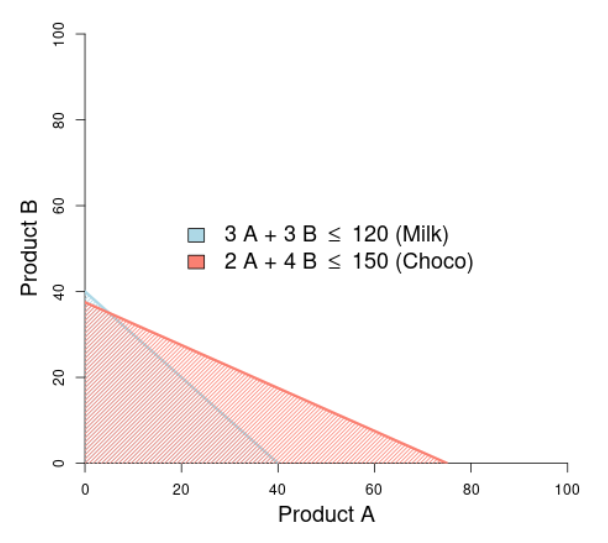

## Task 3

Use linprog

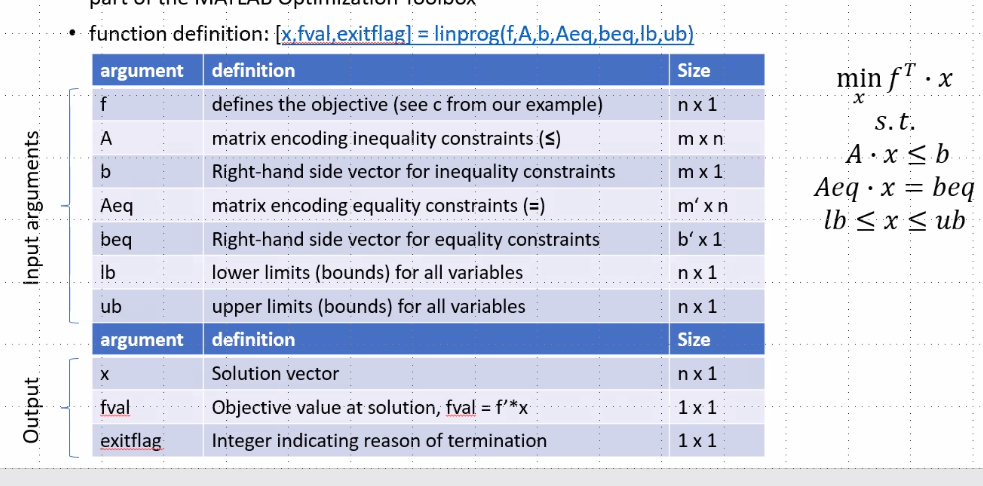

% objective coefficients
f = [-10, -12] % [A, B], negative bc we want to maximize

% constraints
A = [3 3; 2 4]

% auguments/ right-hand-side
b = [120, 150]

% not needed if not specified though...
lb = [0,0]
ub = [100,100] % arbitrarily high

% calculation 
res = linprog(f,A,b)


Solution: 

The maximal profit can be achived with producing 5x Product A and 35x Product B.